# **CSNS Project - Epidemic Simulation**

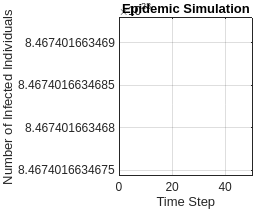

% Set parameters
[infectionRate, recoveryRate, duration] = setParameters();

% Initialize the network
graphErdos = erdosrenyi(100, 0.1); % Example for Erdos-Renyi

### Network Parameters

function [beta, delta, simulationDuration] = setParameters()
    % Set parameters for the epidemic simulation
    beta = 0.2;  % Infection rate
    delta = 0.1; % Recovery rate
    simulationDuration = 50; % Number of simulation steps
end

### Run Simulation

function simulateEpidemic(A, I, beta, delta, simulationDuration)
    n = length(I);
    M = (1 - delta) * eye(n) + beta * A;
    
    % Run the simulation
    for t = 1:simulationDuration
        I = I * M';  % Update infected individuals with the transpose of A
        % Additional logic for recovery, immunity, or other features can be added here
    end
    
    % Plot the results (for simplicity, plotting the evolution of infected individuals)
    plot(1:simulationDuration, sum(I), 'LineWidth', 2);
    xlabel('Time Step');
    ylabel('Number of Infected Individuals');
    title('Epidemic Simulation');
    grid on;
end